## Module 2 project 18

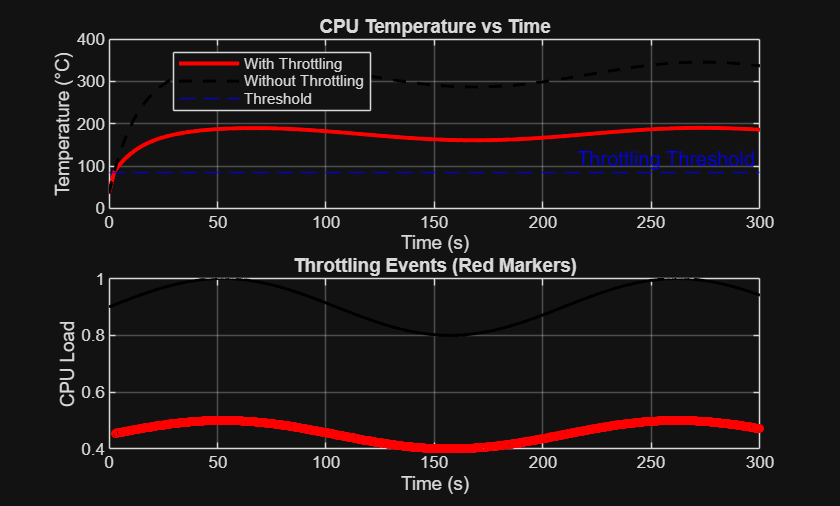

%% Project 18: CPU Thermal Throttling (Computer Engineering)
clear; clc; close all;

%% -------------------------------------------------------------
% 1. Time and CPU load model
% -------------------------------------------------------------
t = 0:0.5:300;          % simulation time (s)
load = 0.9 + 0.1*sin(0.03*t);   % CPU load (0–1), mostly high load

%% -------------------------------------------------------------
% 2. Thermal model (simplified)
%    dT/dt = k1*load - k2*(T - Tamb)
% -------------------------------------------------------------
Tamb = 35;              % ambient temperature (°C)
k1 = 25;                % heating coefficient
k2 = 0.08;              % cooling coefficient

T = zeros(size(t));     % temperature array
T(1) = Tamb;            % start at ambient

%% -------------------------------------------------------------
% 3. Throttling parameters
% -------------------------------------------------------------
Tmax = 85;              % throttling threshold (°C)
throttleFactor = 0.5;   % CPU load reduced by 50% when throttling
isThrottled = false(size(t));

%% -------------------------------------------------------------
% 4. Simulate temperature with throttling
% -------------------------------------------------------------
for i = 2:length(t)
    dt = t(i) - t(i-1);

    % Apply throttling if temperature exceeds limit
    if T(i-1) >= Tmax
        load_eff = load(i) * throttleFactor;
        isThrottled(i) = true;
    else
        load_eff = load(i);
    end

    % Temperature update (Euler integration)
    dT = k1*load_eff - k2*(T(i-1) - Tamb);
    T(i) = T(i-1) + dT*dt;
end

%% -------------------------------------------------------------
% 5. Simulate temperature WITHOUT throttling (for comparison)
% -------------------------------------------------------------
T_noThrottle = zeros(size(t));
T_noThrottle(1) = Tamb;

for i = 2:length(t)
    dt = t(i) - t(i-1);
    dT = k1*load(i) - k2*(T_noThrottle(i-1) - Tamb);
    T_noThrottle(i) = T_noThrottle(i-1) + dT*dt;
end

%% -------------------------------------------------------------
% 6. Plot results
% -------------------------------------------------------------
figure;

subplot(2,1,1)
plot(t, T, 'r', 'LineWidth', 2); hold on;
plot(t, T_noThrottle, 'k--', 'LineWidth', 1.5);
yline(Tmax, 'b--', 'Throttling Threshold');
xlabel('Time (s)');
ylabel('Temperature (°C)');
title('CPU Temperature vs Time');
legend('With Throttling', 'Without Throttling', 'Threshold', 'Location', 'best');
grid on;

subplot(2,1,2)
plot(t, load, 'k', 'LineWidth', 1.5); hold on;
plot(t(isThrottled), load(isThrottled)*throttleFactor, 'ro', 'MarkerSize', 4);
xlabel('Time (s)');
ylabel('CPU Load');
title('Throttling Events (Red Markers)');
grid on;


%% -------------------------------------------------------------
% 7. Written explanation
% -------------------------------------------------------------
fprintf('\nDiscussion:\n');


Discussion:


fprintf(['The CPU temperature rises quickly under sustained high load.\n' ...
         'When the temperature exceeds the safe limit, throttling reduces\n' ...
         'the effective CPU load, slowing the rate of heat generation.\n' ...
         'This prevents runaway temperature increase but reduces performance.\n' ...
         'The comparison shows that without throttling, the CPU would exceed\n' ...
         'safe operating temperatures, while throttling stabilizes the system.\n']);

The CPU temperature rises quickly under sustained high load.
When the temperature exceeds the safe limit, throttling reduces
the effective CPU load, slowing the rate of heat generation.
This prevents runaway temperature increase but reduces performance.
The comparison shows that without throttling, the CPU would exceed
safe operating temperatures, while throttling stabilizes the system.
